### 6.2.2 Calibration of IR-distance sensors

The SMR-CL script has been implemented, and the measurements were logged and are loaded in below. 

data = importdata("logs/6_2_alt_log.dat");

%data = data(1:end, 1:5) % We drop the last row 
% 1 is left 
% 2 is left front
% 3 is middle
% 4 is right front
% 5 is right

data(data(:, 7)== 0, :)= []; % Drop rows where SMR is moving
data = data(:, 1:6); % Don't need that move/not-move column anymore

Lets group by length

% Inspire by the answer from Andrei Boborv: https://www.mathworks.com/matlabcentral/answers/352178-group-an-array-according-a-condition
g = findgroups(data(:,6)); 
[ii,jj] = ndgrid(g,1:size(data,2));
data = accumarray([ii(:),jj(:)],data(:),[],@mean);

Extract the xvalues:

xdata = data(:, 6)*100;
% We can fetch the y data from column 2, 3, 4

We know that the output of the sensor is given as


$$ir_{out}=K_1 \cdot \arctan\left(\frac{K_2}{dist}\right)+K_3$$


- $K_1$ is the scaling factor, limiting the output to 255

- $K_2$ is the distance between the source and the PSD. 

- $K_3$ is an offset

- $dist$ is the distance to the object

However, the above can be simplified


$$ir_{out}=\frac{K_a}{dist}+K_b$$


Which means the distance can be calculated as


$$dist=\frac{K_a}{ir_{out}-K_b}$$


where $K_a$ and $K_b$ has to be calibrated. Let's estimate these two values:

figure;
hold on
labels = ["Left front", "Middle front", "Right front"];
linestyle = ["-.", "--", ":"];
for i = 2:4
    fitted = lsqcurvefit(@irdist, [16,10], xdata, data(:, i));
    f=@(x) (fitted(1)./x+fitted(2));
    x = 10:0.1:100;
    plot(x, f(x), "DisplayName", labels(i-1), LineStyle=linestyle(i-1));
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

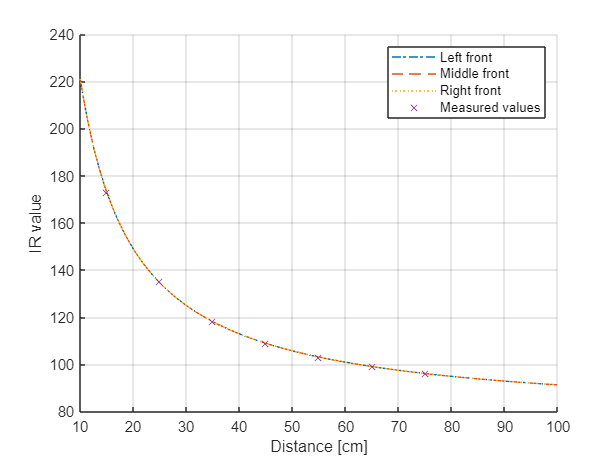

scatter(xdata, data(:,2), 'x', "DisplayName","Measured values") % We just plot for one as they are the same
hold off
grid on
xlabel("Distance [cm]")
ylabel("IR value")
legend show

**Functions**

function irout = irdist(k,d)
    % d is distances in meter 
    % Note that k = [ka kb]
    irout = k(1)./d+k(2);
end